## Ejemplo: Generar un filtro Butterworth pasa bajos y ver su función de transferencia (espectro)

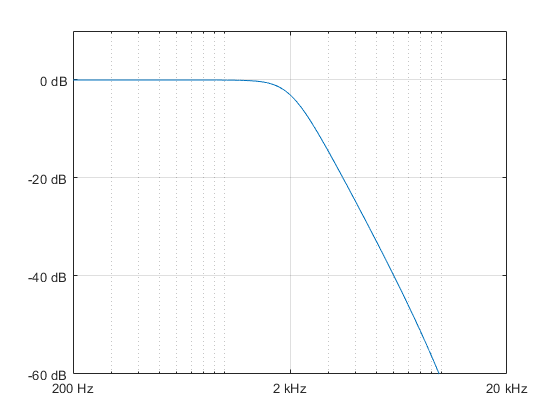

% obtenemos polos y ceros 
fs=48e3;
fc=2e3;
fNyquist=fs/2;
n=4;
Wn = fc/fNyquist;
[b,a]= butter(n,Wn,'low');

%impulso
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;

% usando filter() tengo la respuesta el impulso de ese filtro

h=filter(b,a,impulso);

% fft de h(t) ---> H(F) / grafico.
f=0:1:fs-1;
H = fft(h);
figure(1)
semilogx(f,20*log10(abs(H)));

xticks([200 2000 20000])
yticks([-60 -40 -20 0 10]);
xticklabels({'200 Hz','2 kHz','20 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','0 dB'})
axis([200 20e3 -60 10])
grid on

## 1. Generar un filtro Butterworth pasa altos y ver su función de transferencia (espectro)

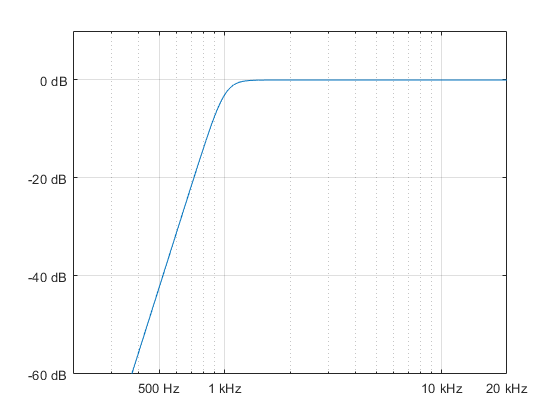

fs=48e3;
fc=1e3;
fNyquist=fs/2;
n=7;
Wn = fc/fNyquist;
[b,a]= butter(n,Wn,'high');

%impulso
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;
%rtaalimpulso
h=filter(b,a,impulso);

% fft de h(t) ---> H(F) / grafico.
f=0:1:fs-1;
H = fft(h);
figure(1)
semilogx(f,20*log10(abs(H)));
ejes=gca;
xticks([0 500 1000 10000 20000])
yticks([-60 -40 -20 0 10]);
xticklabels({'0 Hz','500 Hz','1 kHz','10 kHz','20 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','0 dB'})
axis([200 20e3 -60 10])
grid on

## 2. Generar un filtro Butterworth pasa banda y ver su función de transferencia (espectro)

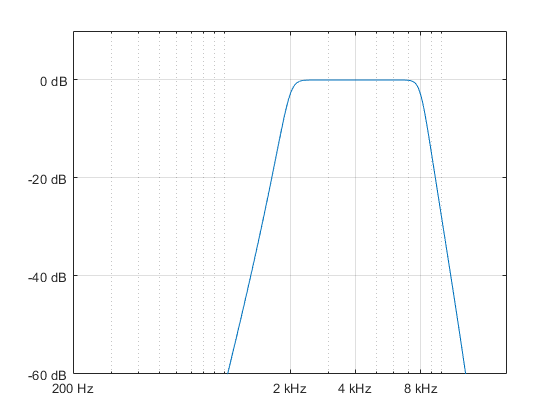

%filtro

fs= 48e3; fNyquist=fs/2;

deltaf=6e3; f0=4e3; n=8;

fc1=(sqrt(deltaf^2+4*f0^2)-deltaf)/2;
fc2=(f0^2)/fc1;

Wn= [fc1/fNyquist fc2/fNyquist];

[b,a]=butter(n,Wn);

%impulso 
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;

%rta

h=filter(b,a,impulso);

%espectro

H=fft(h);

f=0:1:fs-1;
figure(1)
semilogx(f,20*log10(abs(H)));
xticks([200 2000 4000 8000 20000])
yticks([-60 -40 -20 0 10]);
xticklabels({'200 Hz','2 kHz','4 kHz','8 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','0 dB'})
axis([200 20e3 -60 10])
grid on

## 3. Generar un filtro Butterworth rechaza banda y ver su función de transferencia (espectro)

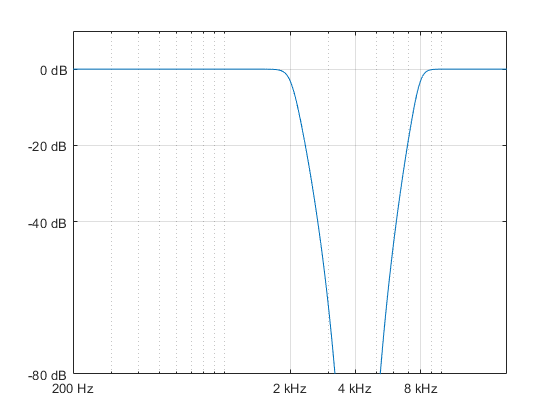


%filtro

fs= 48e3; fNyquist=fs/2;

deltaf=6e3; f0=4e3; n=8;

fc1=(sqrt(deltaf^2+4*f0^2)-deltaf)/2;
fc2=(f0^2)/fc1;

Wn= [fc1/fNyquist fc2/fNyquist];

[b,a]=butter(n,Wn,'stop');

%impulso 
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;

%rta

h=filter(b,a,impulso);

%espectro

H=fft(h);

f=0:1:fs-1;
figure(1)
semilogx(f,20*log10(abs(H)));
xticks([200 2000 4000 8000 20000])
yticks([-80 -40 -20 0 10]);
xticklabels({'200 Hz','2 kHz','4 kHz','8 kHz'})
yticklabels({'-80 dB','-40 dB','-20 dB','0 dB'})
axis([200 20e3 -80 10])
grid on

## 4. Generar un filtro Chevyshev de tipo I pasa bajos y ver su función de transferencia (espectro)

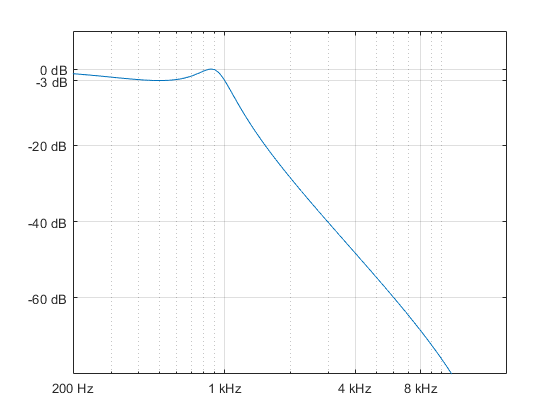

% filtro
fs=48e3;
fc=1e3;
fNyquist=fs/2;
n=3; %sacado del generador de analog devices
Wn = fc/fNyquist;
r=3; %ripple
[b, a] = cheby1(n, r, Wn, 'low');

%impulso
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;

% contorno

h=filter(b,a,impulso);

H=fft(h);

f=0:1:fs-1;
figure(1)
semilogx(f,20*log10(abs(H)));
xticks([200 1000 4000 8000 20000])
yticks([-60 -40 -20 -3 0 10]);
xticklabels({'200 Hz','1 kHz','4 kHz','8 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','-3 dB','0 dB'})
axis([200 20e3 -80 10])
grid on

## 5. Generar un filtro Chevyshev de tipo I pasa altos y ver su función de transferencia (espectro)

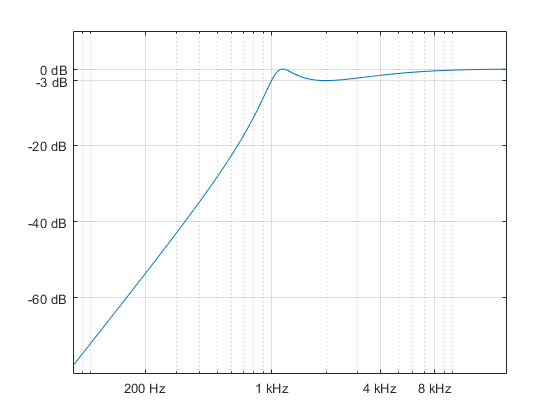

% filtro
fs=48e3;
fc=1e3;
fNyquist=fs/2;
n=3; %sacado del generador de analog devices
Wn = fc/fNyquist;
r=3; %ripple
[b, a] = cheby1(n, r, Wn, 'high');

%impulso
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;

% contorno

h=filter(b,a,impulso);

H=fft(h);

f=0:1:fs-1;

clf
figure(1)
semilogx(f,20*log10(abs(H)));
xticks([200 1000 4000 8000 20000])
yticks([-60 -40 -20 -3 0 10]);
xticklabels({'200 Hz','1 kHz','4 kHz','8 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','-3 dB','0 dB'})
axis([80 20e3 -80 10])
grid on

## 6. Generar un filtro Chevyshev de tipo I pasa banda y ver su función de transferencia (espectro)

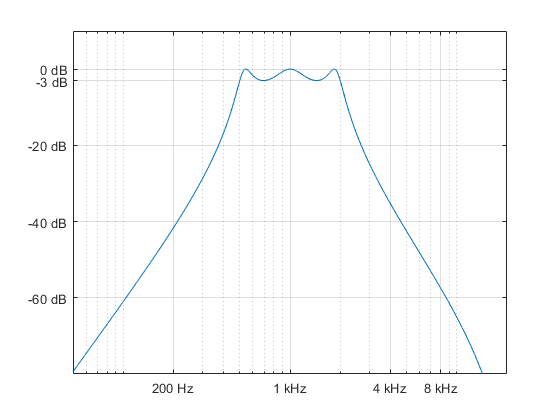

% filtro
fs=48e3;
fc2=2e3; fc1=500;
fNyquist=fs/2;
n=3; %sacado del generador de analog devices
Wn = [fc1/fNyquist fc2/fNyquist];
r=3; %ripple
[b, a] = cheby1(n, r, Wn);

%impulso
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;

% contorno

h=filter(b,a,impulso);

H=fft(h);

f=0:1:fs-1;

clf
figure(1)
semilogx(f,20*log10(abs(H)));
xticks([200 1000 4000 8000 20000])
yticks([-60 -40 -20 -3 0 10]);
xticklabels({'200 Hz','1 kHz','4 kHz','8 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','-3 dB','0 dB'})
axis([50 20e3 -80 10])
grid on

## 7. Generar un filtro Chevyshev de tipo I rechaza banda y ver su función de transferencia (espectro)

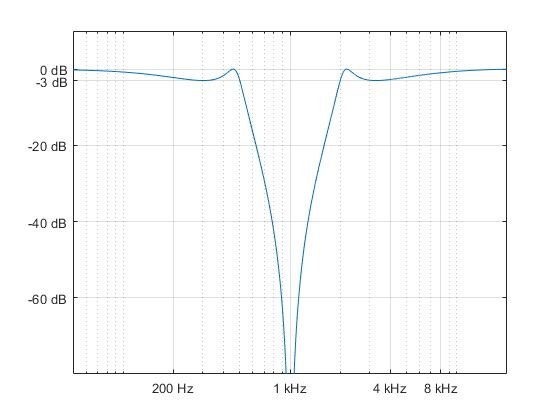

% filtro
fs=48e3;
fc2=2e3; fc1=500;
fNyquist=fs/2;
n=3; 
Wn = [fc1/fNyquist fc2/fNyquist];
r=3; %ripple
[b, a] = cheby1(n, r, Wn,'stop');

%impulso
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;

% contorno

h=filter(b,a,impulso);

H=fft(h);

f=0:1:fs-1;

clf
figure(1)
semilogx(f,20*log10(abs(H)));
xticks([200 1000 4000 8000 20000])
yticks([-60 -40 -20 -3 0 10]);
xticklabels({'200 Hz','1 kHz','4 kHz','8 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','-3 dB','0 dB'})
axis([50 20e3 -80 10])
grid on

## 8. Generar un filtro Chevyshev de tipo II pasa bajos y ver su función de transferencia (espectro)

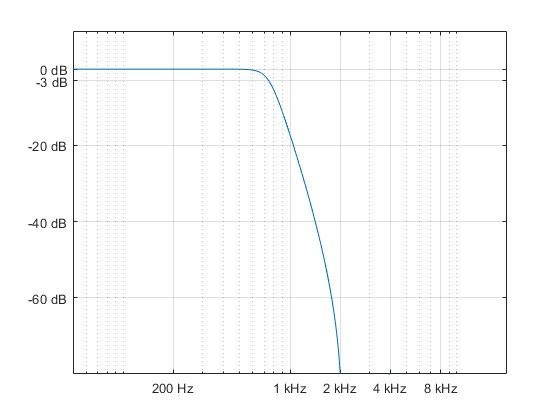

% filtro
fs=48e3;
fc1=2e3;
fNyquist=fs/2;
n=6; 
Wn= fc1/fNyquist;
r=80; % 
[b, a] = cheby2(n, r, Wn);

%impulso
dt=1/fs;
t=0:dt:1-dt;
impulso=0*t; impulso(1)=1;

% contorno

h=filter(b,a,impulso);

H=fft(h);

f=0:1:fs-1;

clf
figure(1)
semilogx(f,20*log10(abs(H)));
xticks([200 1000 2000 4000 8000 20000])
yticks([-60 -40 -20 -3 0 10]);
xticklabels({'200 Hz','1 kHz','2 kHz','4 kHz','8 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','-3 dB','0 dB'})
axis([50 20e3 -80 10])
grid on

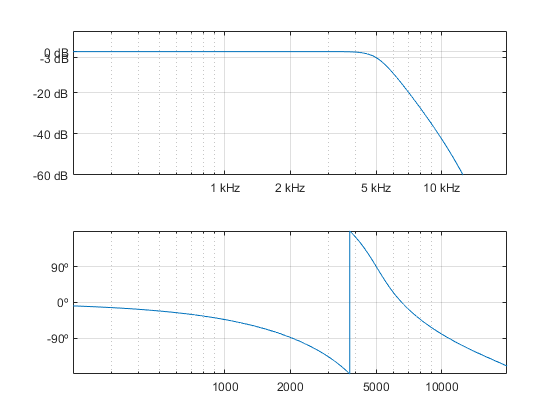

fs=48e3;
fc=5e3;
fNyquist=fs/2;
n=6; 
Wn = fc/fNyquist;
[b,a]=butter(n,Wn);
[H, W] = freqz(b,a,fs);
f = W*fNyquist/pi; %para graficar
fase=angle(H)*180/pi;
figure(1)
subplot(2,1,1)
semilogx(f,20*log10(abs(H)));grid on
axis([200 20e3 -60 10])
xticks([1e3 2e3 5e3 10e3])
yticks([-60 -40 -20 -3 0])
xticklabels({'1 kHz','2 kHz','5 kHz','10 kHz'})
yticklabels({'-60 dB','-40 dB','-20 dB','-3 dB','0 dB'})
subplot(2,1,2)
semilogx(f,fase);grid on
axis([200 20e3 -inf inf])
xticks([1000 2000 5000 10000])
yticks([-2:2]*90)
yticklabels({'-180º','-90º','0º','90º','180º'})

## 9. Generar un filtro Chevyshev de tipo I pasa banda y ver su función de transferencia y fase.

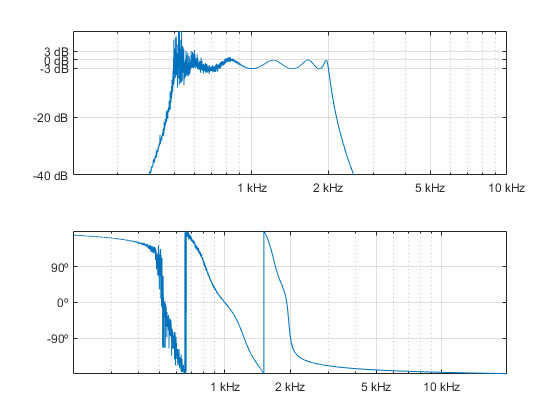

% filtro
fs=48e3; fNyquist=fs/2;
fc1=500; fc2=2e3;

%n=8; 
%n=10;
%n=4;
n=6;
% con orden 8 o mas 'hay cosas raras'
Wn = [(fc1/fNyquist) (fc2/fNyquist)];
r=3; %ripple
[b,a] = cheby1(n, r, Wn);

% contorno

[H,W]=freqz(b,a,fs); % si la resolucion la dejo por defecto, desparece un poco la basura del grafico en las f bajas

f=W*fNyquist/pi;


%fase

fase=angle(H)*180/pi;

%grafico

clf
figure(1)
subplot(2,1,1)
semilogx(f,20*log10(abs(H)));
axis([200 10e3 -40 10])
grid on;
xticks([1e3 2e3 5e3 10e3])
yticks([-40 -20 -3 0 3])
xticklabels({'1 kHz','2 kHz','5 kHz','10 kHz'})
yticklabels({'-40 dB','-20 dB','-3 dB','0 dB','3 dB'})

subplot(2,1,2)
semilogx(f,fase);
axis([200 20e3 -inf inf])
grid on;
xticks([1e3 2e3 5e3 10e3])
yticks([-2:2]*90)
xticklabels({'1 kHz','2 kHz','5 kHz','10 kHz'})
yticklabels({'-180º','-90º','0º','90º','180º'}) 

% no me queda como en la pagina de Analog Devices (para este filtro, seria un 10 orden) 

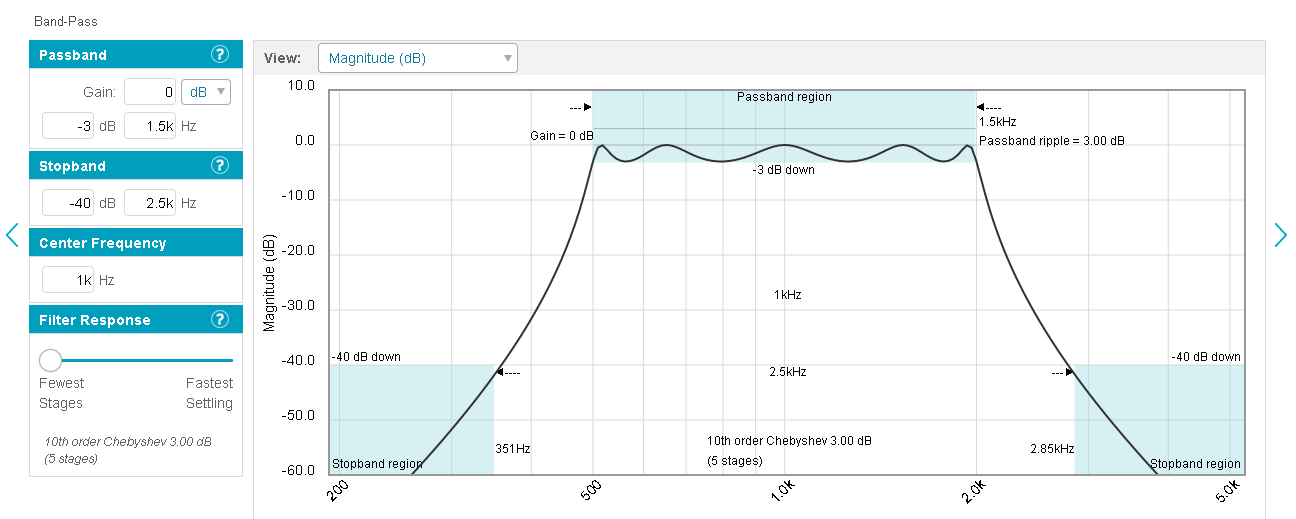

**pre10)**

Primero creamos la señal con componentes senoidales de 1 segundo de duración, graficamos su espectro y la escuchamos

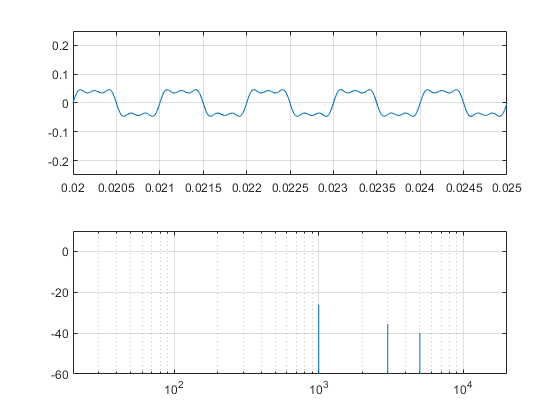

% señal

fs=48e3; fN=fs/2; dt=1/fs;
f1=1e3;
t=0:dt:1-dt;

y=0.05*(sin(2*pi*f1*t)+(1/3)*sin(2*pi*3*f1*t)+(1/5)*sin(2*pi*5*f1*t));

y=y.';

%espectro

f=0:fs-1;
Y=fft(y);

%grafico

figure(1)
subplot(2,1,1)
plot(t,y)
axis([0.02 0.025 -0.25 0.25]); grid on

subplot(2,1,2)
semilogx(f,20*log10(abs(Y)/length(Y)*2))
axis([20 20000 -60 10]); grid on

%sound(y,fs);

Generamos ruido blanco y lo filtramos con un pasabandas de rango estrecho

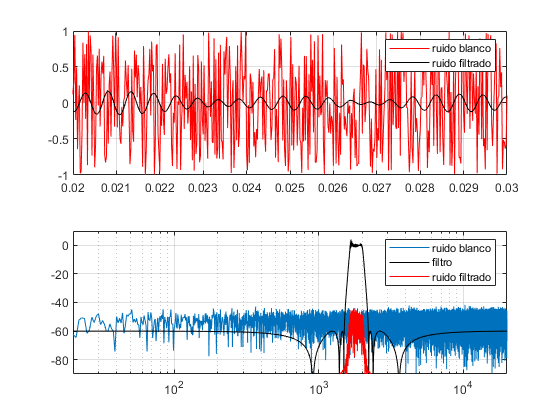


% Ruido
ruido=2*rand(fs,1)-1; 
Ruido=fft(ruido);

%filtro
n=6;
r= 60;
f1=1.5e3; f2=2.2e3;
Wn= [f1/fN f2/fN];

[b,a]=cheby2(n,r,Wn);

[H,W]=freqz(b,a,fs);

% filtrando ruido
ruidoFiltrado=filter(b,a,ruido);
RuidoFiltrado=fft(ruidoFiltrado);

% grafico

figure (1)
subplot(2,1,1) %seÑal
plot(t,ruido,'r',t,ruidoFiltrado,'k')
legend('ruido blanco','ruido filtrado')
axis([0.02 0.03 -1 1]); grid on
subplot(2,1,2) %espectro
semilogx(f,20*log10(abs(Ruido)/length(Y))...
,W/pi*fN,20*log10(abs(H)),'k'...
,f,20*log10(abs(RuidoFiltrado)/length(Y)),'r')

axis([20 20000 -90 10]); grid on
legend('ruido blanco','filtro','ruido filtrado')

sound(ruidoFiltrado,fs)
pause(2);
sound(ruido,fs)

Ensuciamos ahora la señal agregando el ruido filtrado

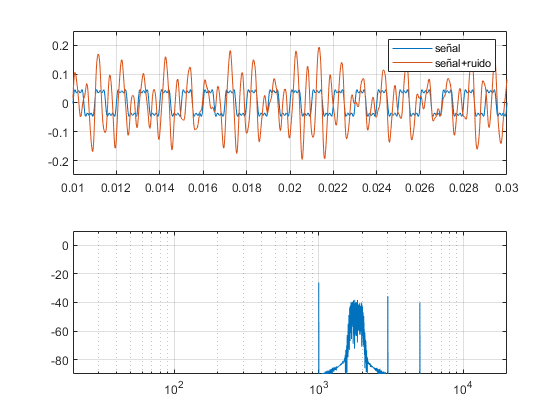

ycRuido=y+ruidoFiltrado; 
YcRuido=fft(ycRuido); 
clf
figure(1)

subplot(2,1,1)
plot(t,y,t,ycRuido)
legend('señal','señal+ruido')
axis([0.01 0.03 -0.25 0.25]); grid on
subplot(2,1,2)
semilogx(f,20*log10(abs(YcRuido)/length(Y)*2))
axis([20 20000 -90 10]); grid on

sound(ycRuido,fs)

Generamos ahora un filtro rechaza banda para que afecte solamente al ruido. Mostramos en el espacio de frecuencias el

espectro del ruido y la función de transferencia del filtro.

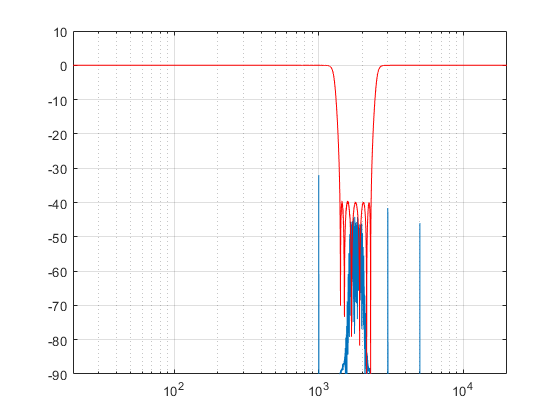

[b2, a2] = cheby2(6,40,[1400 2300]/fN,'stop');
[H2, W2] = freqz(b2,a2,fs);
figure(2)
semilogx(f,20*log10(abs(YcRuido)/length(Y))...
    ,W2/pi*fN,20*log10(abs(H2)),'r')
axis([20 20000 -90 10]); grid on

Filtramos audio con ruido para restaurarlo y escuchamos ambos audios.

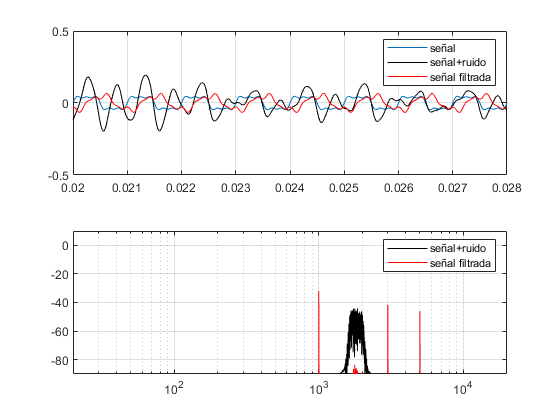

yRestaurado=filter(b2,a2,ycRuido);
YRestaurado=fft(yRestaurado);
clf
figure(1)

subplot(2,1,1)
plot(t,y,t,ycRuido,'k',t,yRestaurado,'r')
legend('señal','señal+ruido','señal filtrada')
axis([0.02 0.028 -0.5 0.5]); grid on

subplot(2,1,2)
semilogx(f,20*log10(abs(YcRuido)/length(Y)),'k'...
    ,f,20*log10(abs(YRestaurado)/length(Y)),'r')
axis([20 20000 -90 10]); grid on
legend('señal+ruido','señal filtrada')



sound(ycRuido,fs)
pause(2)
sound(yRestaurado,fs)

10. Repetir todo este último proceso con un ruido 20 dB menor

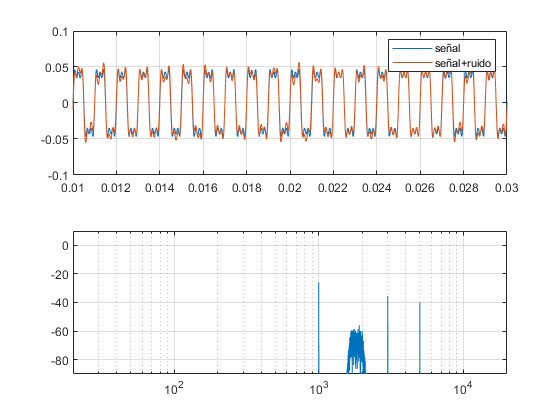

% Ruido -20db
at=10^(-20/20);

ruido=2*rand(fs,1)-1; 
ruido= ruido*at;

Ruido=fft(ruido);

%filtro
n=6;
r= 60;
f1=1.5e3; f2=2.2e3;
Wn= [f1/fN f2/fN];

[b,a]=cheby2(n,r,Wn);

[H,W]=freqz(b,a,fs);

% filtrando ruido
ruidoFiltrado2=filter(b,a,ruido);
RuidoFiltrado2=fft(ruidoFiltrado2);

%seÑal + ruido

yc2=ruidoFiltrado2+y;
Yc2=fft(yc2);

figure(1)

subplot(2,1,1)
plot(t,y,t,yc2)
legend('señal','señal+ruido')
axis([0.01 0.03 -0.1 0.1]); grid on
subplot(2,1,2)
semilogx(f,20*log10(abs(Yc2)/length(Y)*2))
axis([20 20000 -90 10]); grid on 

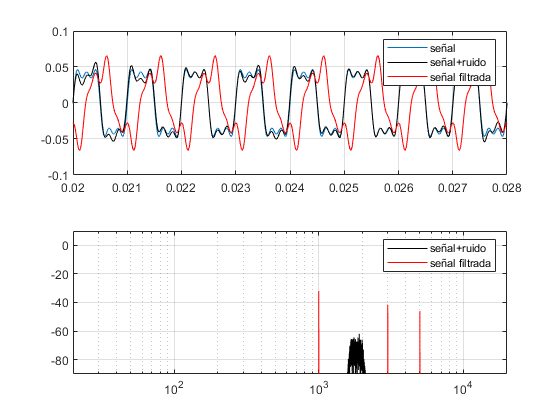

yRestaurado2=filter(b2,a2,yc2);
YRestaurado2=fft(yRestaurado2);

clf
figure(1)

subplot(2,1,1)
plot(t,y,t,yc2,'k',t,yRestaurado2,'r')
legend('señal','señal+ruido','señal filtrada')
axis([0.02 0.028 -0.1 0.1]); grid on

subplot(2,1,2)
semilogx(f,20*log10(abs(Yc2)/length(Y)),'k'...
    ,f,20*log10(abs(YRestaurado2)/length(Y)),'r')
axis([20 20000 -90 10]); grid on
legend('señal+ruido','señal filtrada')

sound(yRestaurado2,fs)
pause(3)
sound(yc2,fs)
pause(3)
sound(y,fs)